## 基于短时归一化自相关函数的语音端点检测

基本原理：噪声的自相关函数、（含躁）语音的自相关函数，按帧看，有很大的区别，可用于提取语音信号的端点。

% pr6_3_3  
clear all; clc; close all;

run Set_I                               % 基本设置

fle = 'bluesky1.wav'

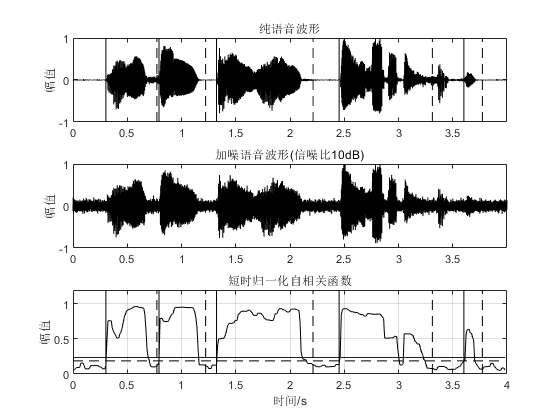

   1     30     77


   2     79    122


   3    132    221


   4    245    331


   5    360    377


run PART_I                              % 读入数据，分帧等准备
[n,Wn]=buttord(300/(fs/2),600/(fs/2),3,20); % 计算滤波器阶数和带宽
[bs,as]=butter(n,Wn);                   % 求取数字滤波器系数
for k=1 : fn
    u=y(:,k);                           % 取一帧数据
    ru=xcorr(u);                        % 计算自相关函数
    rnu=ru/max(ru);                     % 归一化
    rpu=filter(bs,as,rnu);              % 数字滤波
    Ru(k)=max(rpu);                     % 寻找最大值
end
Rum=multimidfilter(Ru,10);              % 平滑处理
thredth=max(Rum(1:NIS));                % 设置阈值
T1=1.2*thredth;
T2=1.5*thredth;
[voiceseg,vsl,SF,NF]=vad_param1D(Rum,T1,T2);   % 单参数双门限端点检测

% 作图
subplot 311; plot(time,x,'k');
title('纯语音波形');
ylabel('幅值'); axis([0 max(time) -1 1]);
subplot 312; plot(time,signal,'k');
title(['加噪语音波形(信噪比' num2str(SNR) 'dB)']);
ylabel('幅值'); axis([0 max(time) -1 1]);
subplot 313; plot(frameTime,Rum,'k');
title('短时归一化自相关函数'); grid; ylim([0 1.2]);
xlabel('时间/s'); ylabel('幅值'); 
line([0,frameTime(fn)], [T1 T1], 'color','k','LineStyle','--');
line([0,frameTime(fn)], [T2 T2], 'color','k','LineStyle','-');
% 标出语音端点
for k=1 : vsl
    nx1=voiceseg(k).begin; nx2=voiceseg(k).end;
    fprintf('%4d   %4d   %4d\n',k,nx1,nx2);
    subplot 311; 
    line([frameTime(nx1) frameTime(nx1)],[-1 1],'color','k','LineStyle','-');
    line([frameTime(nx2) frameTime(nx2)],[-1 1],'color','k','LineStyle','--');
    subplot 313; 
    line([frameTime(nx1) frameTime(nx1)],[0 1.2],'color','k','LineStyle','-');
    line([frameTime(nx2) frameTime(nx2)],[0 1.2],'color','k','LineStyle','--');
end